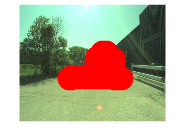

lidarP = pcread("pcd/set_1.pcd");
imName = "png/set_1.jpg";
P_lidar = transpose(lidarP.Location);
P_lidar = [P_lidar;ones(1,size(P_lidar,2))];
    
P_cam = transpose(tform.T) * P_lidar;
    
P_cam_homo = P_cam(1:3,:) ./ P_cam(4,:);
P_img_homo = cameraParams.Intrinsics.K * P_cam_homo;
P_img = P_img_homo(1:2,:) ./ P_img_homo(3,:);
imshow(imName)
hold on
scatter(P_img(1, :), P_img(2, :), 'r', 'filled');
hold off